# Obserevers Design

JJRATH- Feb2021 Closed Loop Luenberger Observer Based Controller Design

%--------------------------
%----------------------------
% Ex1: Active Suspension System
% qcar_CT = SISO_Nom_Suspension; % The nominal suspension model
qcar_CT = SISO_Dis_suspension; % The disturbed suspension model
t = 0:.01:10-0.01;
% For state feedback control all states are required.
% Lets design observer to estimate the states
% From pole placement, our closed loop controller poles are at:
% We want our observer poles to be much farther away. So lets place our
% desired poles as:


p_des = [-12,-10,-15,-0.1];


%  p_des = 10*[-.1+5.2457i,-.1-5.2457i,-1+42.6209i,-1-42.6209i ];

L=place(qcar_CT.a',qcar_CT.c',p_des); % Design observer gains by duality expression
L = L';



%---- Closed Loop Observer
A_cl=[qcar_CT.a ,zeros(size(qcar_CT.a));
      L*qcar_CT.c,  qcar_CT.a-L*qcar_CT.c];
B_cl=[qcar_CT.b;qcar_CT.b(:,1),qcar_CT.b(:,2)*0];
C_cl=[qcar_CT.c zeros(size(qcar_CT.c));zeros(size(qcar_CT.c)) qcar_CT.c];
D_cl=zeros(2,2);
%--- Closed Loop System
CLo_qcarCT = ss(A_cl,B_cl,C_cl,D_cl); % Observer closed loop system

## Simulate Estimation Performance for the Nominal System (i.e. No Road

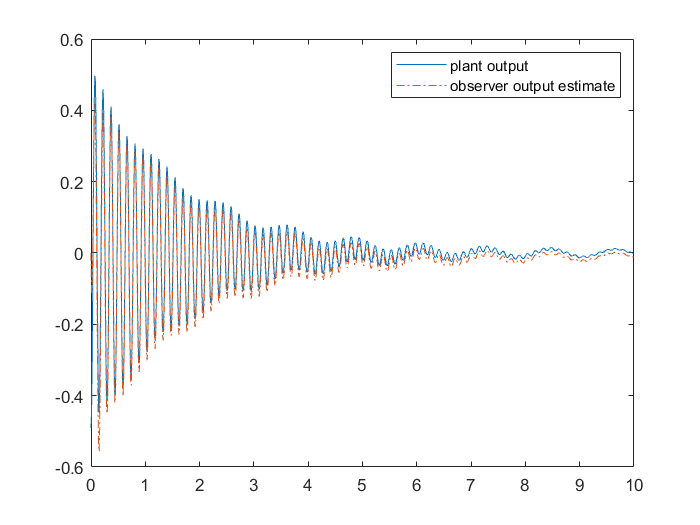

%disturbance)
u_f = 0.1*ones(1,length(t)); % Nominal input of magnitude 0.1
xp = [0.01 0.1 0.5 .1]'; % Initial conditions are  non- zero.
xO = zeros(1,4)';
[Y_CLO,t,X_CLO] = lsim(CLo_qcarCT,[u_f; u_f*0],t,[xp;xO]);
%--------------
figure; plot(t,Y_CLO(:,1),t,Y_CLO(:,2),'-.') % first state of the observer is the position of the mass
legend('plant output','observer output estimate')

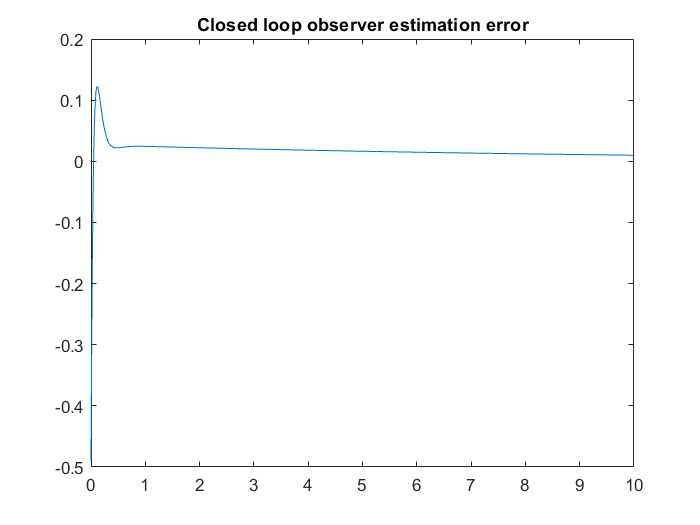

figure;
plot(t,Y_CLO(:,1)-Y_CLO(:,2)); 
title('Closed loop observer estimation error')

## Simulate Estimation Performance for the Distrubed System (i.e. Road

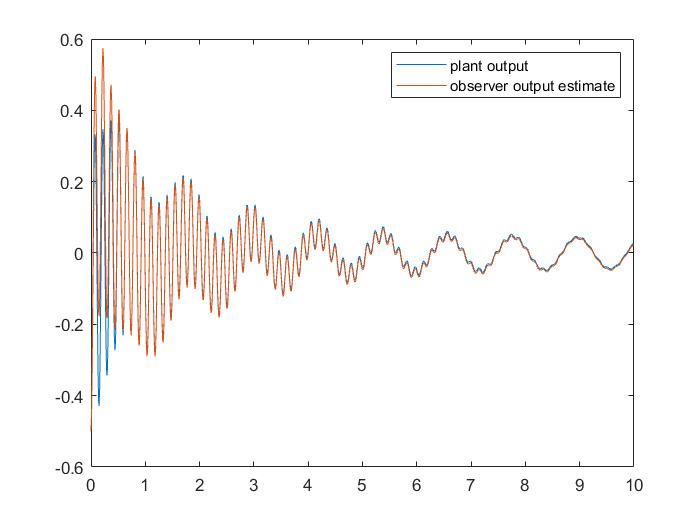

%disturbance) % NOte that observer has no information of distrurbance
u_f = 0.1*ones(1,length(t)); % Nominal input of magnitude 0.1
xp = [0.01 0.1 0.5 .1]'; % Initial conditions are  non- zero.
xO = [0 0.1 0.5 .1]';
[Y_CLO,t,X_CLO] = lsim(CLo_qcarCT,[u_f; u_f],t,[xp;xO]);
%--------------
figure; plot(t,Y_CLO(:,1),t,Y_CLO(:,2)) % first state of the observer is the position of the mass
legend('plant output','observer output estimate')

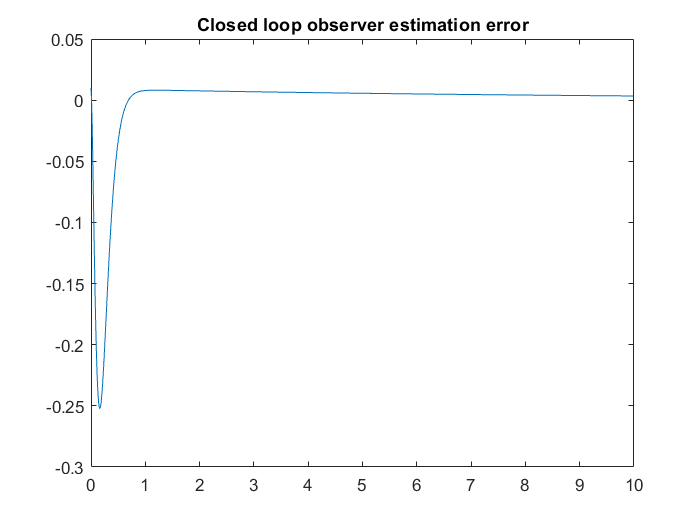

figure;
plot(t,Y_CLO(:,1)-Y_CLO(:,2)); 
title('Closed loop observer estimation error')